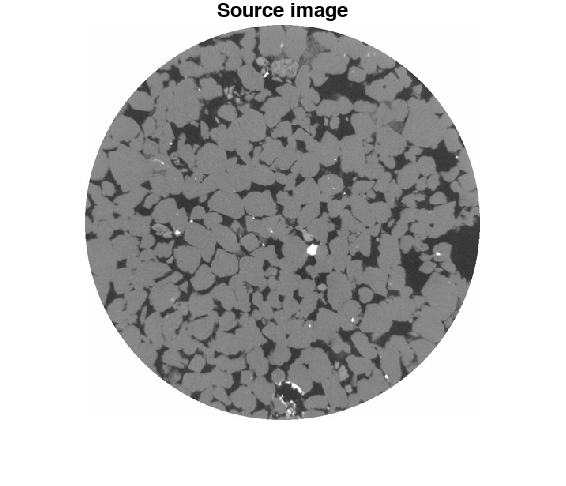

% Load image
I = im2double(imread('granite.png'));
figure(1); imshow(I); title('Source image');

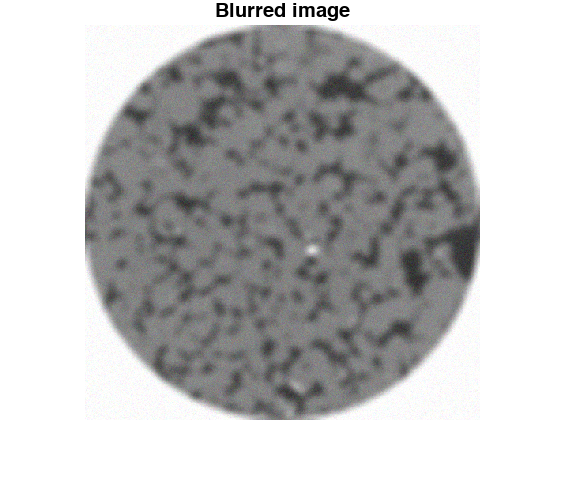


% Blur image
PSF = fspecial('gaussian', 15, 5);
Blurred = imfilter(I, PSF,'circular','conv');

% Add noise
noise_mean = 0.001;
noise_var = 0.001;
Blurred = imnoise(Blurred, 'gaussian', noise_mean, noise_var);
figure(2); imshow(Blurred); title('Blurred image');

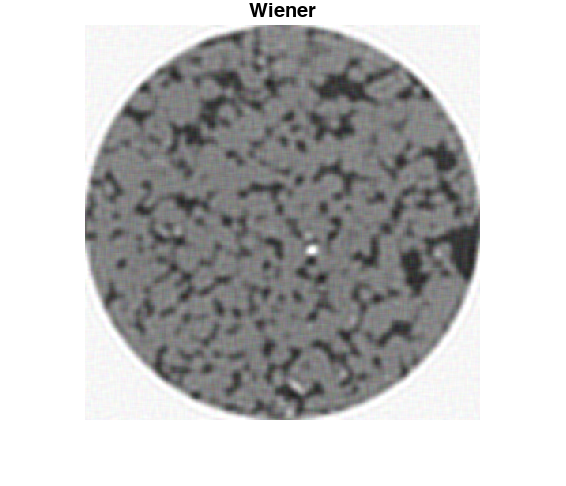

estimated_nsr = noise_var / var(Blurred(:));

% Restore image
figure(3), imshow(deconvwnr(Blurred, PSF, estimated_nsr)), title('Wiener');

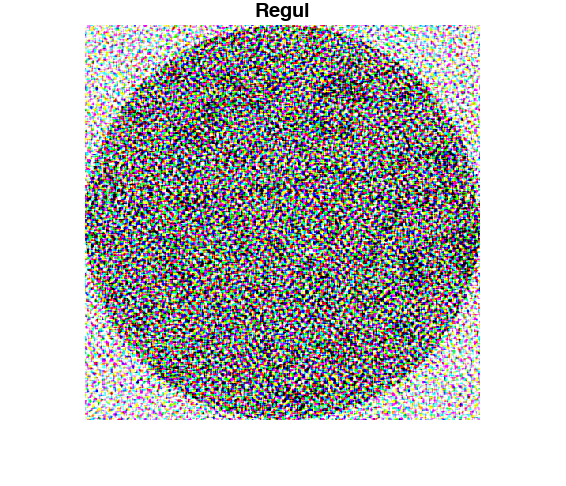

figure(4); imshow(deconvreg(Blurred, PSF)); title('Regul');

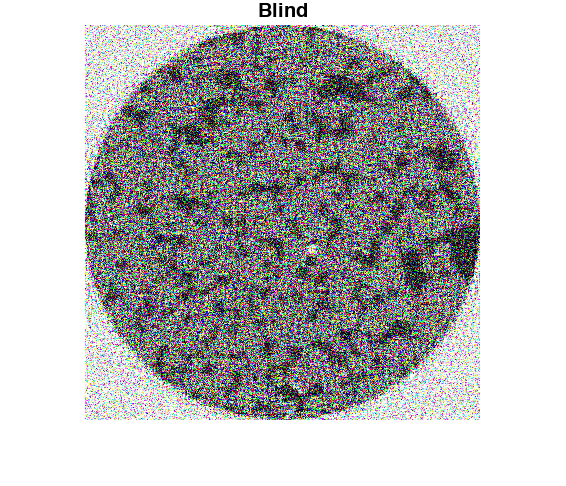

figure(5); imshow(deconvblind(Blurred, PSF, 100));
title('Blind');

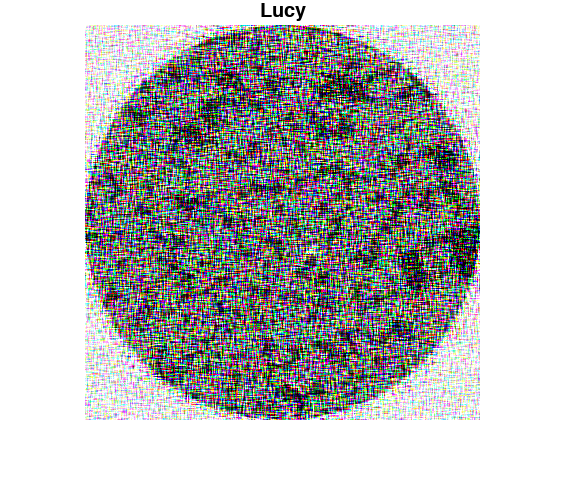

figure(6); imshow(deconvlucy(Blurred, PSF, 100));
title('Lucy');